clc                     % clear command window
clear                   % clear MATLAB workspace
% profile on            % profi\le used to time each segment of code

## **Set up robot control system** ( code that runs once )

% Set up Raspberry Pi
disp('note: It takes a 10 seconds or so to download code to Raspberry PI '); 

note: It takes a 10 seconds or so to download code to Raspberry PI 


[robotPi, blinkLED]= RaspPiSetup()

robotPi =   raspi with properties:

         DeviceAddress: '192.168.34.15'               
                  Port: 18734                         
             BoardName: 'Raspberry Pi Model B+'       
         AvailableLEDs: {'led0'}                      
  AvailableDigitalPins: [4,5,6,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27]
  AvailableSPIChannels: {'CE0','CE1'}                 
     AvailableI2CBuses: {'i2c-1'}                     
      AvailableWebcams: {'bcm2835-isp (platform:bcm2835-isp)','mmal service 16.1 (platform:bcm2835-v4l2)'}
           I2CBusSpeed: 100000                        

  Supported peripherals


blinkLED = 'led0'



% Turn on board LED on and off to signal program has started 
%Blink(robotPi,blinkLED,10);
disp('Warning! Robot Rover Active! ');

Warning! Robot Rover Active! 



% Set up servos, PiCam, and QWIIC analog input
% [roverServos, roverJoy] = ServoSetup(robotPi)
% [robotCam] = PiCamSetup(robotPi)
% [adcDevice1, adcDevice2] = QWIICInputSetup(robotPi)
[neo] = GPSSetup(robotPi)

neo =   NEO_M8U with properties:

       DEFAULT_I2C_BUS: 'i2c-1'
    DEFAULT_HW_ADDRESS: '0x42'
          DEFAULT_NAME: "I2C_NEO_M8U"
                   ubx: [1×1 UBX]
                device: [1×1 raspi.internal.I2Cdev2]
                  data: []


clear waypoints
index = 1;
while 1
    gtest=input('Ready to exit? type Y then hit enter','s');
    if gtest == 'Y'
        break
    else
  
        latitude = 0;
        longitude = 0;
        for i = 1:25
            basic_data = neo.getBasic();
            latitude = latitude + basic_data.lattitude;
            longitude = longitude + basic_data.longitude;
        end
        latitude = latitude/25;
        longitude = longitude/25;
        waypoints(index, 1) = latitude
        waypoints(index, 2) = longitude
        index = index + 1;
        % save file in case of crashing
        save("waypoints2.mat", 'waypoints')
    end
end

**Visualize GPS Data**

waypoints(:,1)

ans =    42.3268
   33.7032
   42.2932
   42.2931
   42.2931
   33.7032
   42.2933


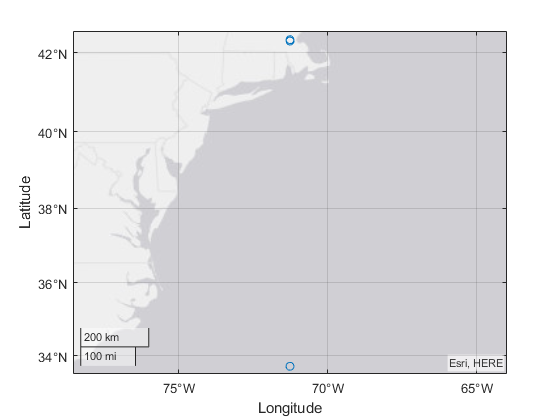

geoscatter(waypoints(:, 1), waypoints(:,2))

function [neo] = GPSSetup(robotPi)
neo = NEO_M8U(robotPi);            % Create a GPS Class Instance
pause(2);                          % Let GPS get up to speed
% returns a struct with fields: longitude, lattitude, roll, pitch, and heading.
end
function [robotPi, blinkLED] = RaspPiSetup()
% RaspPiSetup creates and configures a Raspberry Pi to be a simple robot 
% controller. It requires no inputs and returns a rasPi object

% Create a *raspi* object.
%    robotPi = raspi('192.168.16.65', 'pi', 'raspberry');   % lab pi
   robotPi = raspi('192.168.34.15', 'pi', 'raspberry');   % melody pi
 
% There is a user LED on Raspberry Pi hardware that you can turn on and
% off. Execute the following command at the MATLAB prompt to turn the LED
% off and then turn it on again.
   blinkLED = robotPi.AvailableLEDs{1};
end
